% Katherine Lasonde
% T1 grapher for NV center

v = load('t1_cmost.sfit', '-mat');
my_model = v.savedSession.AllFitdevsAndConfigs{1, 1}.Fitdev.Fit

my_model =      General model:
     my_model(x) = a*exp(-x/b)+c
     Coefficients (with 95% confidence bounds):
       a =         0.5  (-0.04483, 1.045)
       b =       185.5  (39.71, 331.4)
       c =      0.9159  (0.9025, 0.9293)

% Plot
filename = 't1_qis_data_real.xlsx'; 

% Pull out the data
data = readtable(filename, 'VariableNamingRule', 'preserve');
time_axis = (data.Var1(2:end));
photon_num_axis = (data.Var2(2:end));
% stnd_dev = (data.Deviation(2:end));

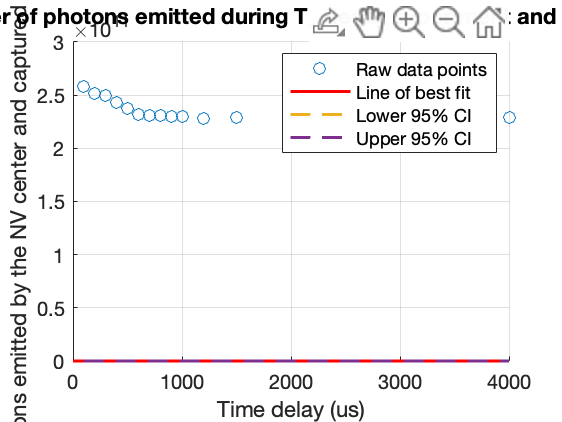

x = time_axis;
y = photon_num_axis;
ci = predint(my_model, x);
figure()
hold on;
scatter(time_axis, photon_num_axis,LineWidth=0.2);
h = plot(my_model, 'r');
h.LineWidth = 1.5;
plot(x, ci, '--', LineWidth=1.5);
% errorbar(time_axis, photon_num_axis, stnd_dev, 'k');
hold off;
grid;
legend('Raw data points', 'Line of best fit', 'Lower 95% CI', 'Upper 95% CI')
title("Time delay (us) vs. Number of photons emitted during T_1 decay experiment and captured by the Photodiode");
xlabel('Time delay (us)') ;
ylabel('Number of photons emitted by the NV center and captured by the Photodiode');